% Load ONNX network
% net = importONNXNetwork("D:\college\FYP\Colab\Pytorch\ResNet_18_v1\n5s_resnet18.onnx");

% Class names
load("D:\college\FYP\Colab\Pytorch\ResNet_18_v1\5s_class_names.mat")
class_names = cellstr(class_names)

class_names = 10×1 cell array
    {'No_Parking'                    }
    {'No_Parking_Damaged'            }
    {'Parking'                       }
    {'Parking_Damaged'               }
    {'Road_Construction_Sign'        }
    {'Road_Construction_Sign_Damaged'}
    {'Stop'                          }
    {'Stop-Damaged'                  }
    {'Zebra_Crossing'                }
    {'Zebra_Crossing_Damaged'        }



% Load the test dataset directory
test_dir = "D:\college\FYP\Colab\Pytorch\test";  % Update with the correct path
image_files = dir(fullfile(test_dir, '**', '*.png'));

% Initialize variables for accuracy calculation and confusion matrix
correct = 0;
total = 0;
true_labels = [];
predicted_labels = [];

% Loop through the images
for i = 1:numel(image_files)
    % Preprocess the input image
    img = imread(fullfile(image_files(i).folder, image_files(i).name));
    img = imresize(img, [224 224]);
    img = single(img) / 255;  % Normalize pixel values to [0, 1] and convert to single
    
    % Make a prediction
    out = predict(net, img);
    
    % Get the predicted class index
    [~, idx] = max(out);
    predClass = class_names{idx};
    
    % Extract true label from folder name
    true_label = strsplit(image_files(i).folder, filesep);
    true_label = true_label{end};
    
    % Update counters for accuracy calculation
    total = total + 1;
    if strcmp(true_label, predClass)
        correct = correct + 1;
    end
    
    % Store true and predicted labels for confusion matrix
    true_labels{end+1} = true_label;
    predicted_labels{end+1} = predClass;
end

% Calculate accuracy
accuracy = (correct / total) * 100;
disp(['Test Accuracy: ' num2str(accuracy) '%']);

Test Accuracy: 86.1878%


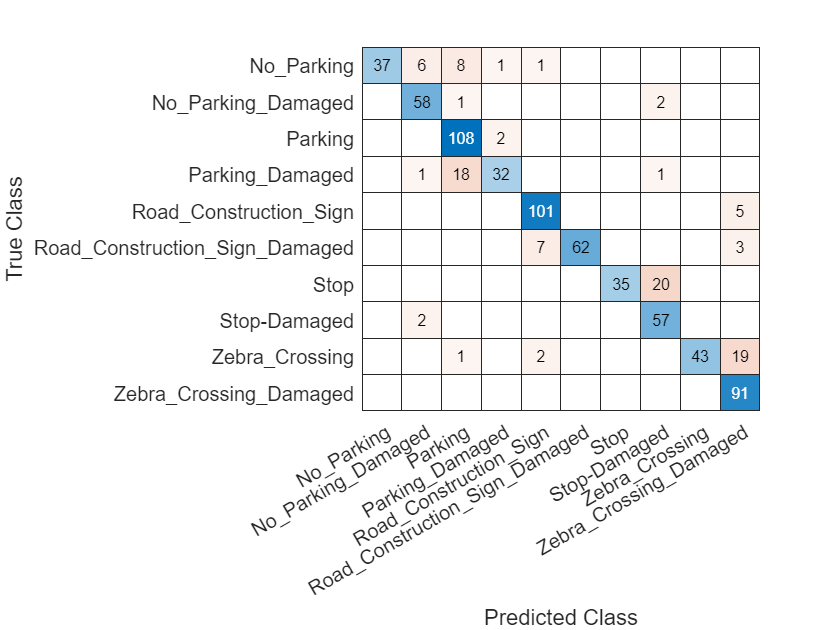


% Create confusion matrix
confusion = confusionchart(true_labels, predicted_labels);